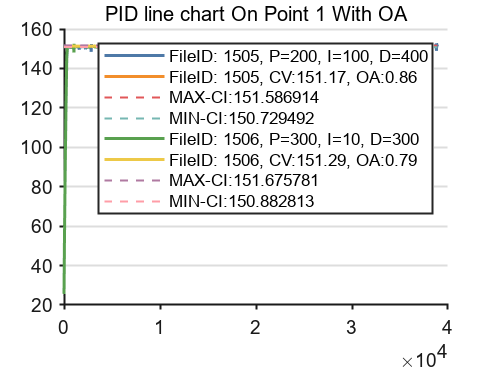

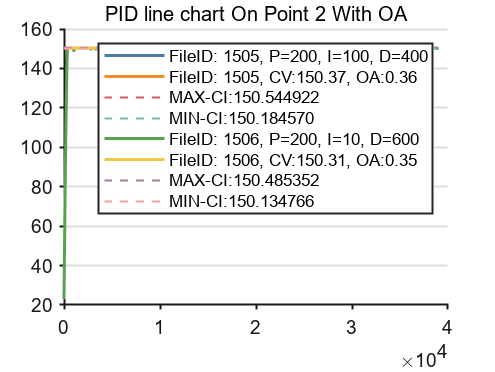

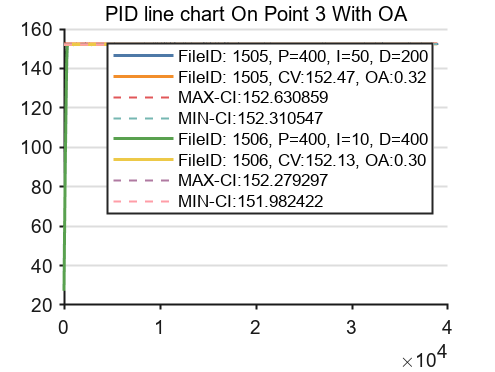

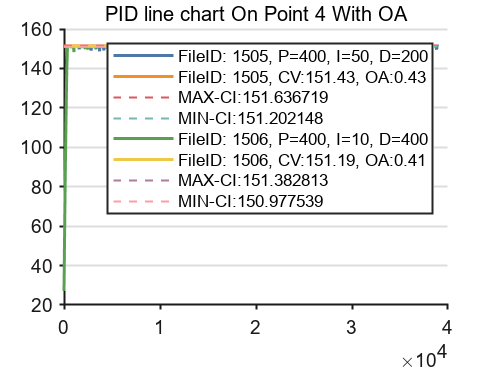

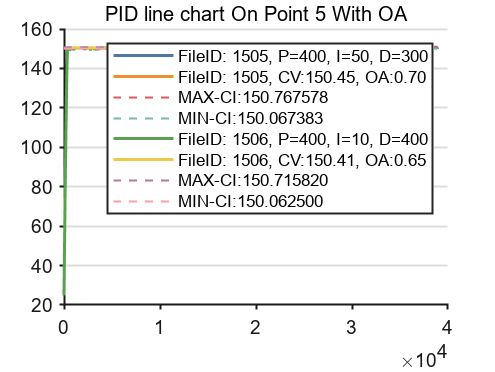

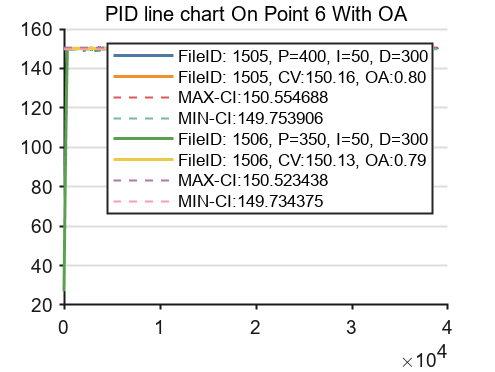

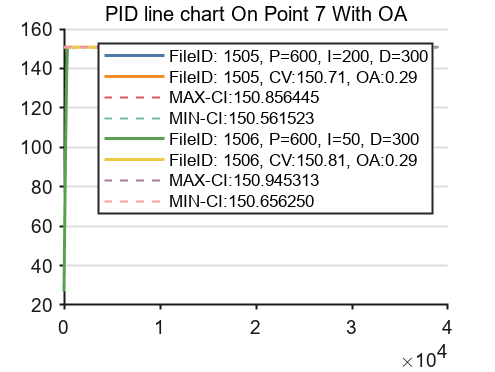

% 加载绘图数据
run("DataAnalysis_LoadVariables.m");
% 加载颜色集
run("Color.m");
% 定义类枚举变量选择绘图模式
way_to_plot = way.OnePointOneFigureWithOA;


% ------------------------------ 绘制各个数据文件中共同测温点的曲线图 ------------------------------
if way_to_plot == way.OnePointOneFigure
    close all;
    clc;
    for i = 1:1:7
    %     subplot(4,2,i);
        figure;
        for j = 1:1:FilesNum
            if namestr(j) == "temp1505" || namestr(j) == "temp1506"
                    pidcellbuffer = piddic(namestr{j});
                    plot(XCell{j},table2array(DataCell{1, j}(:,i)), ...
                         "DisplayName",sprintf("FileID: %s, P=%s, I=%s, D=%s",extractBetween(namestr(j),5,8),pidcellbuffer{1}(i,1),pidcellbuffer{1}(i,2),pidcellbuffer{1}(i,3)), ...
                         "LineWidth", 1.5);
                    hold on;
                    plot(XCell{j},repmat(CenterValue(j, i),height(DataCell{1, j}),1), ...
                         "DisplayName",sprintf("FileID: %s, CV:%.6f",extractBetween(namestr(j),5,8),CenterValue(j, i)), ...
                         "LineWidth", 1.5);
                    hold on;
            end
        end
        set(gca,'Box','off', ...                                % 边框开关
            'LineWidth',1, ...                                  % 线宽（非数据线）
            'XGrid','off','YGrid','on', ...                     % 网格开关
            'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
            'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
            'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
        legend;
        colororder(color1002);
        title(sprintf("PID line chart with different SetTemp on Point %d",i));
        hold off;
    end
end


% ------------------------------ 绘制各个数据文件中七个测温点的曲线图 ------------------------------
if way_to_plot == way.AllPointsOneFigure
    close all;
    for i = 1:1:FilesNum
        figure(i);
        for j = 1:1:7
            pidcellbuffer = piddic(namestr{i});
            plot(XCell{i},table2array(DataCell{i}(:,j)), ...
                 "DisplayName",sprintf("Point: %d, P=%s, I=%s, D=%s",j,pidcellbuffer{1}(j,1),pidcellbuffer{1}(j,2),pidcellbuffer{1}(j,3)), ...
                 "LineWidth", 1.5);
            hold on
        end
        set(gca,'Box','off', ...                                % 边框开关
            'LineWidth',1, ...                                  % 线宽（非数据线）
            'XGrid','off','YGrid','on', ...                     % 网格开关
            'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
            'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
            'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
        legend;
        colororder(color1002);
        title(sprintf("PID line chart. SetTemp: %s",extractAfter(namestr{i},"temp")));
        hold off;
    end
end

% ------------------------------ 绘制各个数据文件中共同测温点的曲线图 - 不同文件的同点在一张图中分组绘制 ------------------------------
if way_to_plot == way.OnePointDifferentAxes
    close all;
    clc;
    for i = 1:1:7
        figure;
        for j = 1:1:FilesNum
            if 1 % namestr{j} ~= "temp1501"
                subplot(floor(sqrt(FilesNum)),floor(sqrt(FilesNum))+1,j);
                pidcellbuffer = piddic(namestr{j});
                plot(XCell{j},table2array(DataCell{1, j}(:,i)), ...
                     "DisplayName",sprintf("FileID: %s, P=%s, I=%s, D=%s",extractBetween(namestr(j),5,8),pidcellbuffer{1}(i,1),pidcellbuffer{1}(i,2),pidcellbuffer{1}(i,3)), ...
                     "LineWidth", 1.5);
                hold on;
                plot(XCell{j},repmat(CenterValue(j, i),height(DataCell{1, j}),1), ...
                     "DisplayName",sprintf("CV:%.6f",CenterValue(j, i)), ...
                     "LineWidth", 1.5);
                hold on;
                plot(XCell{j},repmat(DataCell{3,j}(i,1),height(DataCell{1, j}),1), ...
                     "DisplayName",sprintf("MAX-CI:%.6f",DataCell{3,j}(i,1)), ...
                     "LineWidth", 1,"LineStyle","--");
                hold on;
                plot(XCell{j},repmat(DataCell{3,j}(i,2),height(DataCell{1, j}),1), ...
                     "DisplayName",sprintf("MIN-CI:%.6f",DataCell{3,j}(i,2)), ...
                     "LineWidth", 1,"LineStyle","--");
                set(gca,'Box','off', ...                                % 边框开关
                    'LineWidth',1, ...                                  % 线宽（非数据线）
                    'XGrid','off','YGrid','on', ...                     % 网格开关
                    'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
                    'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
                    'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
                legend;
                colororder(color1006);
                title(sprintf("PID line chart on Point %d File %s OA %.2f",i,namestr{j},(DataCell{3,j}(i,1)-DataCell{3,j}(i,2))));
                hold off;
            end
        end
    end
end

% ------------------------------ 绘制选中文件的七个温点的独立曲线图，带上下区间 ------------------------------
if way_to_plot == way.OnePointOneFigureWithOA
    close all;
    clc;
    for i = 1:1:7
    %     subplot(4,2,i);
        figure;
        for j = 1:1:FilesNum
            if namestr(j) == "temp1505" || namestr(j) == "temp1506"
                    pidcellbuffer = piddic(namestr{j});
                    plot(XCell{j},table2array(DataCell{1, j}(:,i)), ...
                         "DisplayName",sprintf("FileID: %s, P=%s, I=%s, D=%s",extractBetween(namestr(j),5,8),pidcellbuffer{1}(i,1),pidcellbuffer{1}(i,2),pidcellbuffer{1}(i,3)), ...
                         "LineWidth", 1.5);
                    hold on;
                    plot(XCell{j},repmat(CenterValue(j, i),height(DataCell{1, j}),1), ...
                         "DisplayName",sprintf("FileID: %s, CV:%.2f, OA:%.2f",extractBetween(namestr(j),5,8),CenterValue(j, i),(DataCell{3,j}(i,1)-DataCell{3,j}(i,2))), ...
                         "LineWidth", 1.5);
                    hold on;
                    plot(XCell{j},repmat(DataCell{3,j}(i,1),height(DataCell{1, j}),1), ...
                         "DisplayName",sprintf("MAX-CI:%.6f",DataCell{3,j}(i,1)), ...
                         "LineWidth", 1,"LineStyle","--");
                    hold on;
                    plot(XCell{j},repmat(DataCell{3,j}(i,2),height(DataCell{1, j}),1), ...
                         "DisplayName",sprintf("MIN-CI:%.6f",DataCell{3,j}(i,2)), ...
                         "LineWidth", 1,"LineStyle","--");
            end
        end
        set(gca,'Box','off', ...                                % 边框开关
            'LineWidth',1, ...                                  % 线宽（非数据线）
            'XGrid','off','YGrid','on', ...                     % 网格开关
            'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
            'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
            'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
        legend;
        colororder(color1002);
        title(sprintf("PID line chart On Point %d With OA",i));
        hold off;
    end
end